duration_params = readtable("./output/duration_distributions/allrisk_base_mu_sigma_samples.csv");
intensity_params = readtable("./output/severity_distributions/taleb_params_samples.csv");

duration_sampler = DurationSampler(duration_params);
intensity_sampler = ParametrizedSeveritySampler(intensity_params, 0.01);

draws = unifrnd(0, 1, [height(duration_params), 200]);

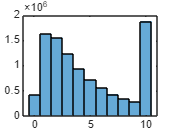

durations = duration_sampler.get_duration(draws);
histogram(durations);

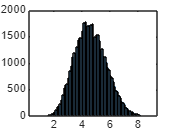

histogram(mean(durations, 2));

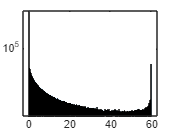

intensity_samples = intensity_sampler.get_severity(draws);
histogram(intensity_samples); set(gca, 'YScale', 'log');

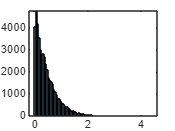

histogram(mean(intensity_samples, 2));